# 1117_Matlab上机实验

`1)`**   分别创建**`2000*2000`**大小的稀疏矩阵和普通矩阵，非零值服从高斯分布，比较二者存储空间的差别，并打印结果**

m=2000;n=2000;
tic
R = normrnd(0,1,m,n);
toc

历时 0.037109 秒。


tic
V = sprandn(m,n,0.1);
toc

历时 0.035655 秒。


**2）试用MATLAB 分别计算多项式 f(x)=20x^3-7x^2+5x+10 , g(x)=4x^2+12x-3的和与差**

a = [20,-7,5,10];
b = [4,12,-3];
poly2sym(a)

$$ans = 20\,x^{3}-7\,x^{2}+5\,x+10$$

poly2sym(b)

$$ans = 4\,x^{2}+12\,x-3$$

poly2sym(a+[0,b])

$$ans = 20\,x^{3}-3\,x^{2}+17\,x+7$$

poly2sym(a-[0,b])

$$ans = 20\,x^{3}-11\,x^{2}-7\,x+13$$

**3）已知 f(x)=20x^3-7x^2+5x+10, g(x)=4x^2+12x-3, p(x)=6x^3+4x^2-5, q(x)=12x^3-7x^2+3x+9，试用MATLAB表示f(x)*g(x)*p(x)*q(x)**

a = [20,-7,5,10];
b = [4,12,-3];
c = [6,4,0,-5];
d = [12,-7,3,9];
res = conv(conv(conv(a,b),c),d);
poly2sym(res)

$$ans = 5760\,x^{11}+15744\,x^{10}-8456\,x^{9}+6328\,x^{8}+16478\,x^{7}+10368\,x^{6}-16088\,x^{5}+1841\,x^{4}+11040\,x^{3}-9150\,x^{2}-4275\,x+1350$$

**4）	已知 f(x)=20x^3-7x^2+5x+10 , g(x)=4x^2+12x-3。试利用MATLAB计算f(x)除以g(x)的商与余项式（如果存在）**

a = [20,-7,5,10];
b = [4,12,-3];
res = deconv(a,b);
poly2sym(res)

$$ans = 5\,x-\frac{67}{4}$$

**5)根据1), 2) and 3)中得到的多项式, 在 x属于[0. 20]的范围内利用MATLAB绘制多项式的曲线，并计算上述多项式在x=0, 2, 5, 10 ,20下的值. （提示：这里需要用到MATLAB中的“polyval” 和“plot” 函数）**

% 2)
a = [20,-7,5,10];
b = [4,12,-3];
% poly2sym(a)
% poly2sym(b)
res1 = a+[0,b];
res2 = a-[0,b];
poly2sym(res1)

$$ans = 20\,x^{3}-3\,x^{2}+17\,x+7$$

poly2sym(res2)

$$ans = 20\,x^{3}-11\,x^{2}-7\,x+13$$

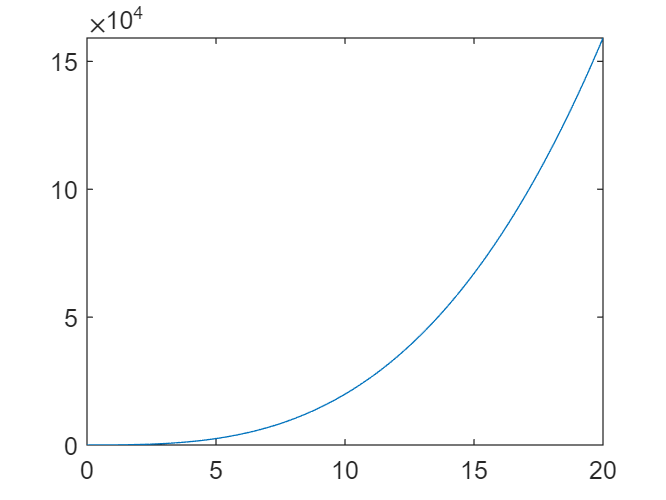

x = linspace(0,20,100);
y1 = polyval(res1,x);
y2 = polyval(res2,x);
plot(x,y1);

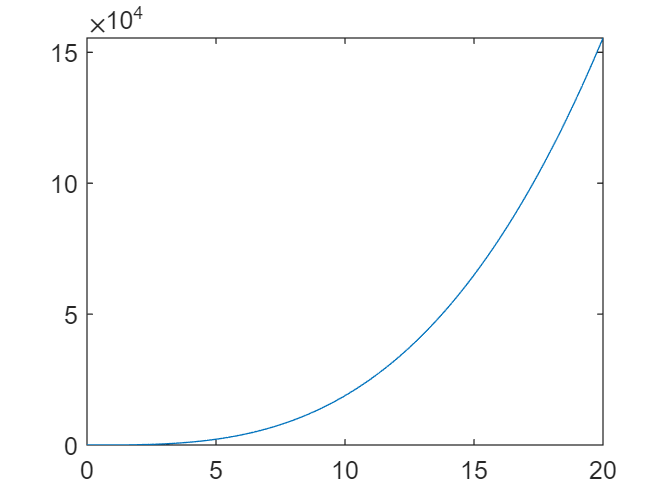

plot(x,y2);

y1_ret = polyval(res1,[0,2,5,10,20])

y1_ret =            7         189        2517       19877      159147


y2_ret = polyval(res2,[0,2,5,10,20])

y2_ret =           13         115        2203       18843      155473


% 3)
a = [20,-7,5,10];
b = [4,12,-3];
c = [6,4,0,-5];
d = [12,-7,3,9];
res = conv(conv(conv(a,b),c),d);
poly2sym(res)

$$ans = 5760\,x^{11}+15744\,x^{10}-8456\,x^{9}+6328\,x^{8}+16478\,x^{7}+10368\,x^{6}-16088\,x^{5}+1841\,x^{4}+11040\,x^{3}-9150\,x^{2}-4275\,x+1350$$

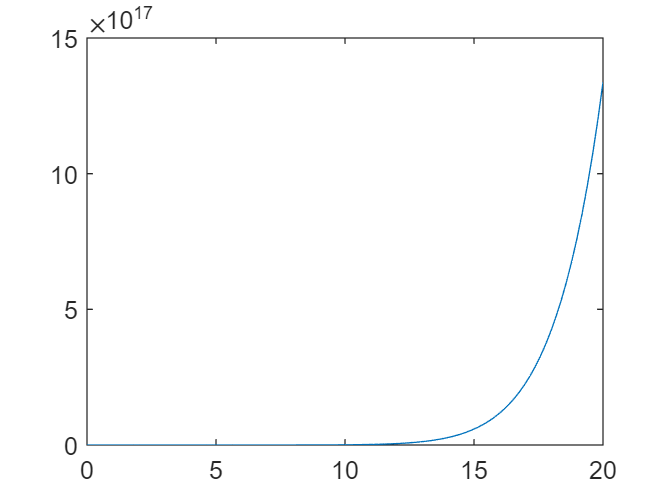

x = linspace(0,20,100);
y = polyval(res,x);
plot(x,y);

y = polyval(res,[0,2,5,10,20])

y = 1.0e+18 *

    0.0000    0.0000    0.0000    0.0007    1.3367


% 4)
a = [20,-7,5,10];
b = [4,12,-3];
res = deconv(a,b);
poly2sym(res)

$$ans = 5\,x-\frac{67}{4}$$

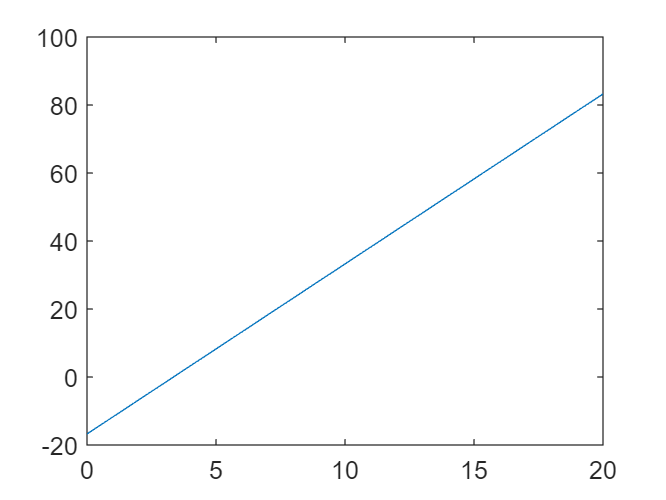

x = linspace(0,20,100);
y = polyval(res,x);
plot(x,y);

y = polyval(res,[0,2,5,10,20])

y =   -16.7500   -6.7500    8.2500   33.2500   83.2500


**6) 已知 f(x)=20x^3-7x^2+5x+10, g(x)=4x^2+12x-3，试利用MATLAB求多项式f(x)*g(x)的微分项**

a = [20,-7,5,10];
b = [4,12,-3];
tmp = conv(a,b);
res = polyder(tmp);
poly2sym(res)

$$ans = 400\,x^{4}+848\,x^{3}-372\,x^{2}+242\,x+105$$

**7) 试用MATLAB求解方程x^4+5x^3-7x^2+27x+10=0的全部解**

a = [1,5,-7,27,10];
poly2sym(a)

$$ans = x^{4}+5\,x^{3}-7\,x^{2}+27\,x+10$$

roots(a)

ans =   -6.6343 + 0.0000i
   0.9846 + 1.8795i
   0.9846 - 1.8795i
  -0.3348 + 0.0000i


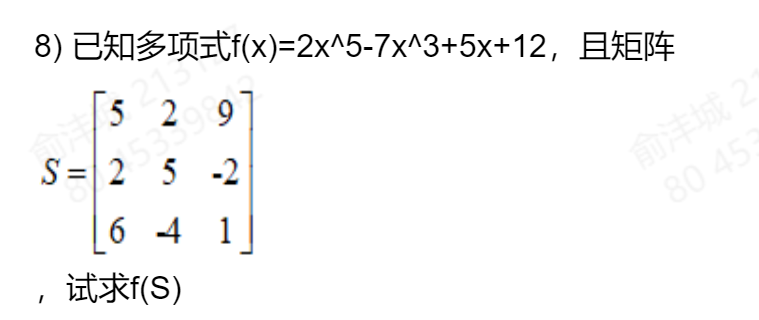

a = [2,0,-7,0,5,12];
poly2sym(a)

$$ans = 2\,x^{5}-7\,x^{3}+5\,x+12$$

S =[5,2,9;2,5,-2;6,-4,1];
polyval(a,S)

ans =         5412          30      113052
          30        5412          -6
       14082       -1608          12


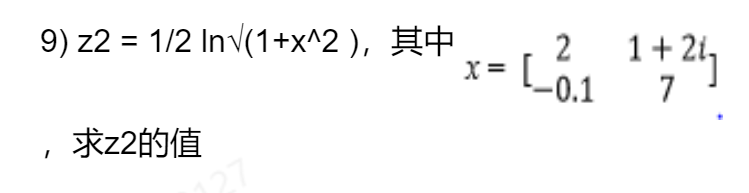

x = sym('x');
z2 = (1/2)*log(sqrt(1+x^2));
X = [2,1+2i;-0.1,7];
res = (1/2)*log(sqrt(1+X^2))

res =    0.3975 - 0.0102i   0.7562 + 0.2659i
  -0.5756 + 0.0000i   0.9775 - 0.0010i


**10）y1=x2-4x+4, y2 = x - 2，求y1/y2、y1的微分、y2的积分**

a = [1,-4,4];
b = [1,-2];
c = deconv(a,b);
d = polyder(c)

d = 1

e = polyder(a)

e =      2    -4


f = polyint(b)

f =     0.5000   -2.0000         0
